**The C5-2V convex ultrasound transducer is a type of curved array transducer commonly used in abdominal, pelvic, and obstetric imaging.**

**Similar to other ultrasound transducers, the frequency of the C5-2V convex transducer affects its performance in several ways:**

- **Resolution: Higher frequency ultrasound waves have shorter wavelengths, which leads to better resolution and detail in the resulting image. However, higher frequency also means shallower penetration depth. With convex transducers, higher frequency settings (e.g., 5 MHz) are commonly used for superficial structures such as the liver and spleen.**

- **Penetration: Lower frequency ultrasound waves have longer wavelengths, which allows them to penetrate deeper into the body. However, this can result in lower resolution and less detailed images. With convex transducers, lower frequency settings (e.g., 2 MHz) are commonly used for deeper structures such as the uterus and bladder.**

- **Imaging depth: The imaging depth of an ultrasound transducer is dependent on its frequency. Higher frequency transducers provide shallower imaging depth while lower frequency transducers offer deeper imaging depth. With convex transducers, the imaging depth can vary depending on the application and anatomical location being imaged.**

**Therefore, selecting the appropriate frequency setting for the C5-2V convex ultrasound transducer depends on the clinical scenario and imaging goals. Higher frequency settings are typically used for superficial structures while lower frequency settings are used for deeper structures. The imaging depth can also vary based on the frequency setting and the anatomical location being imaged.**

param = struct with fields:
           fc: 2500000
         kerf: 4.8000e-05
        width: 4.6000e-04
        pitch: 5.0800e-04
    Nelements: 128
    bandwidth: 79
       radius: 0.0496
       height: 0.0135
        focus: 0.0600


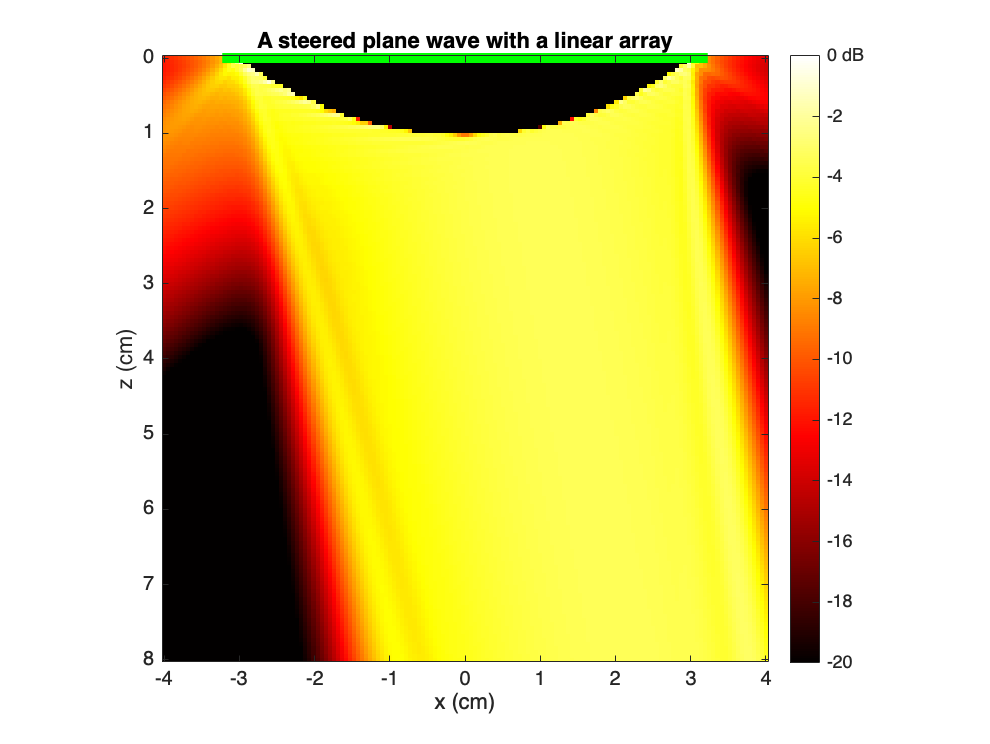

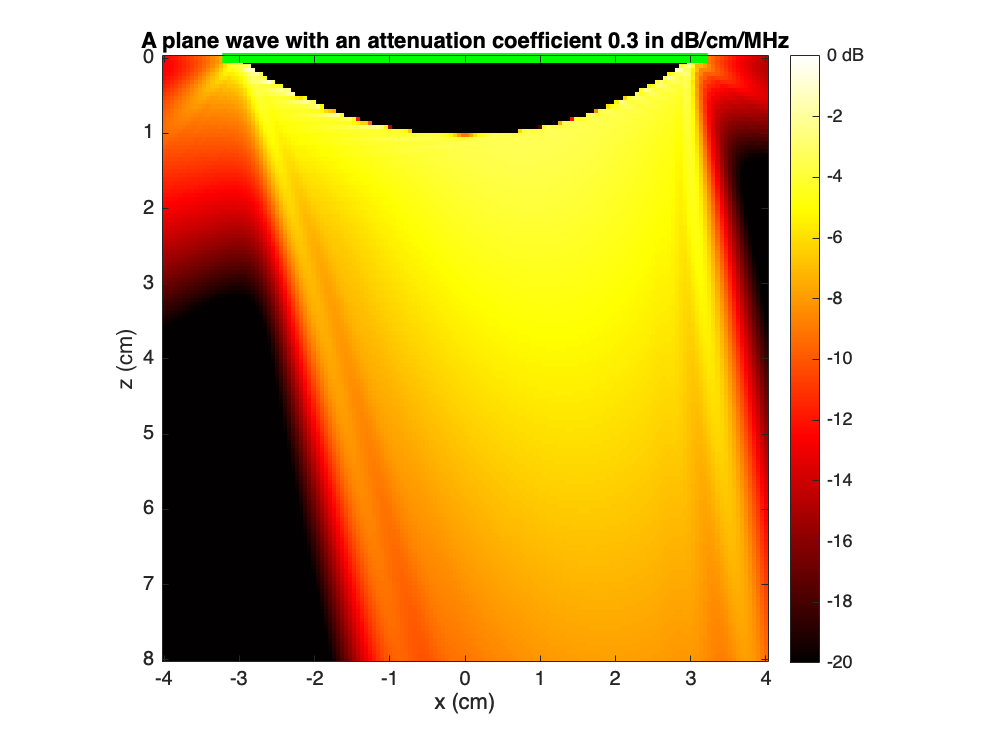

param = struct with fields:
             fc: 3570000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 0.3000


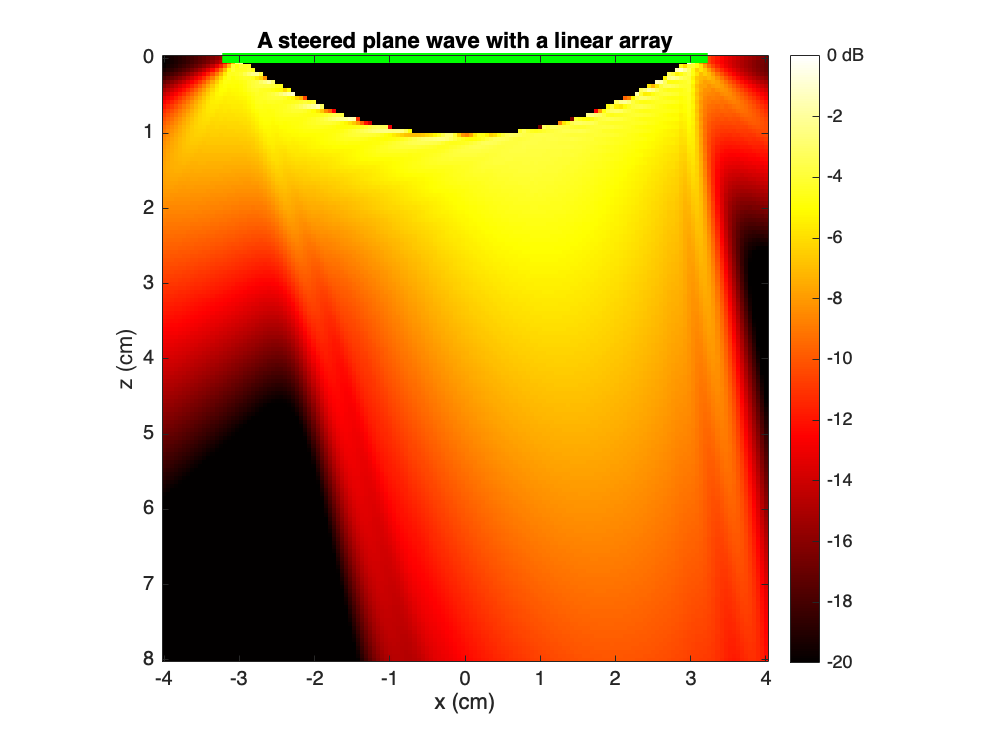

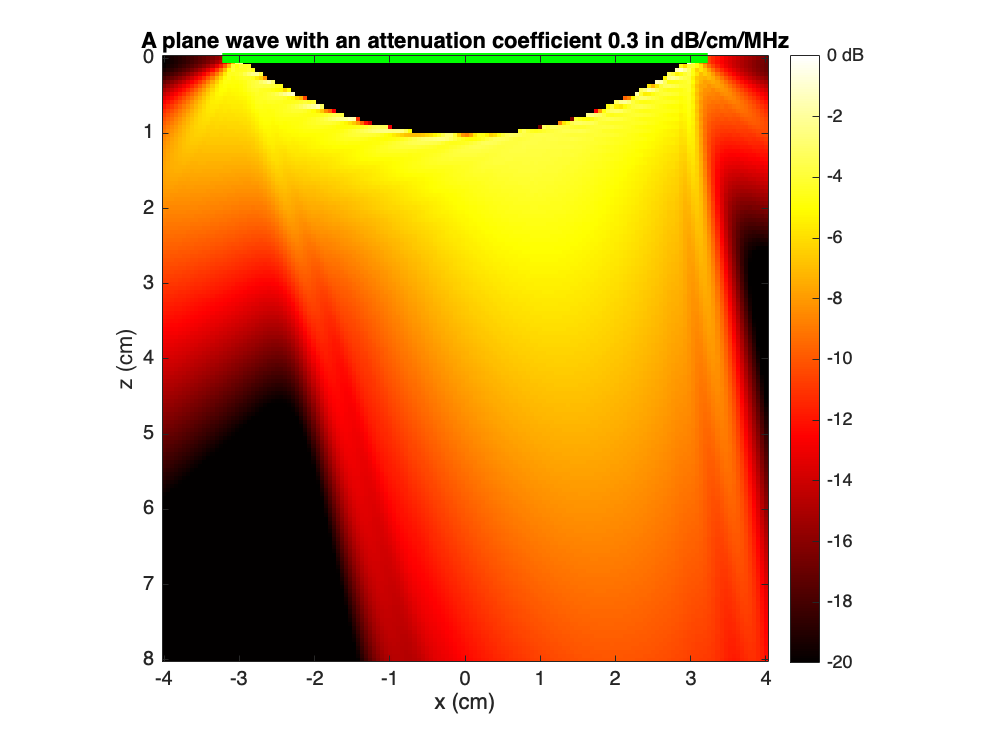

param = struct with fields:
             fc: 7500000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 0.3000


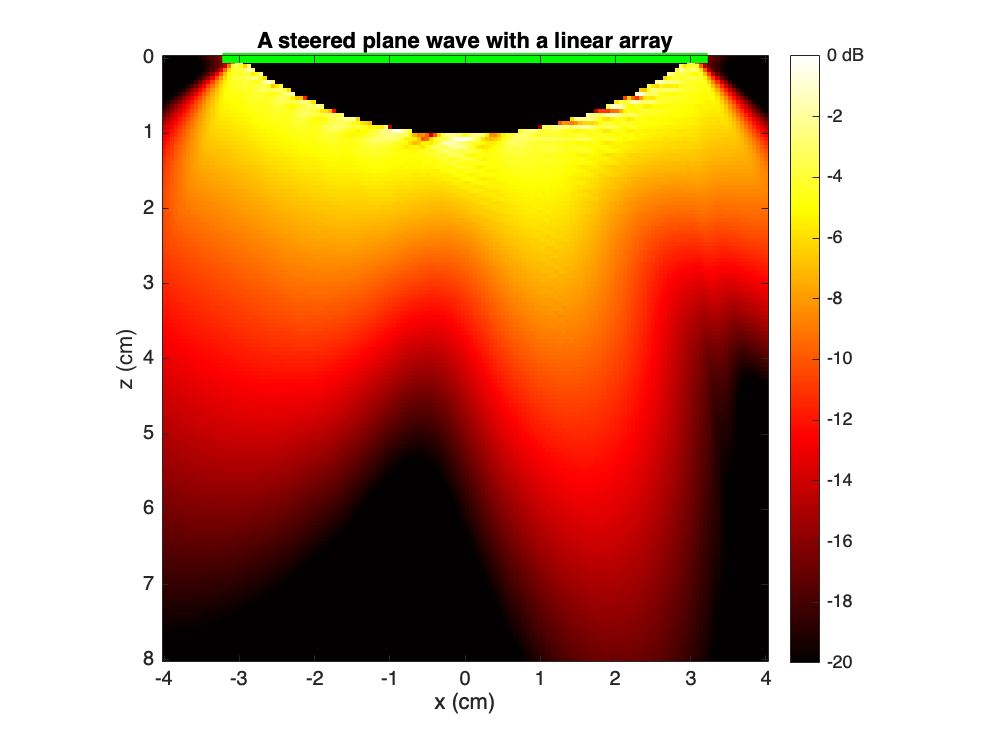

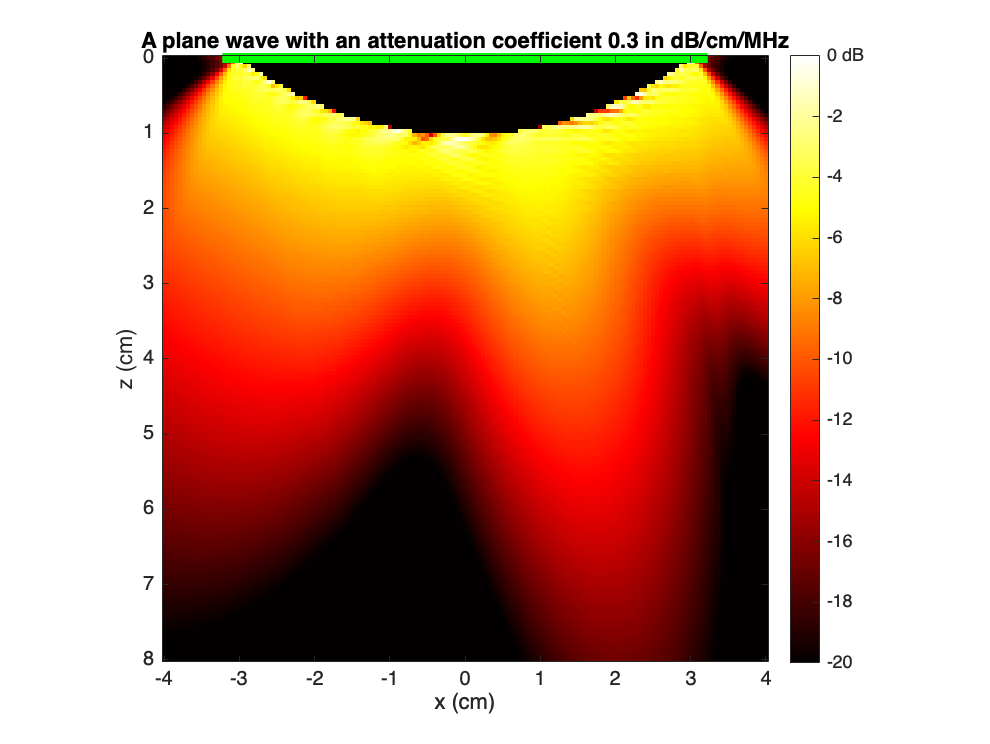

   
param = getparam('C5-2v');

freq_linear = [2.5e6, 3.57e6, 7.5e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 0.3;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 0.3 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end

param = struct with fields:
           fc: 2500000
         kerf: 4.8000e-05
        width: 4.6000e-04
        pitch: 5.0800e-04
    Nelements: 128
    bandwidth: 79
       radius: 0.0496
       height: 0.0135
        focus: 0.0600


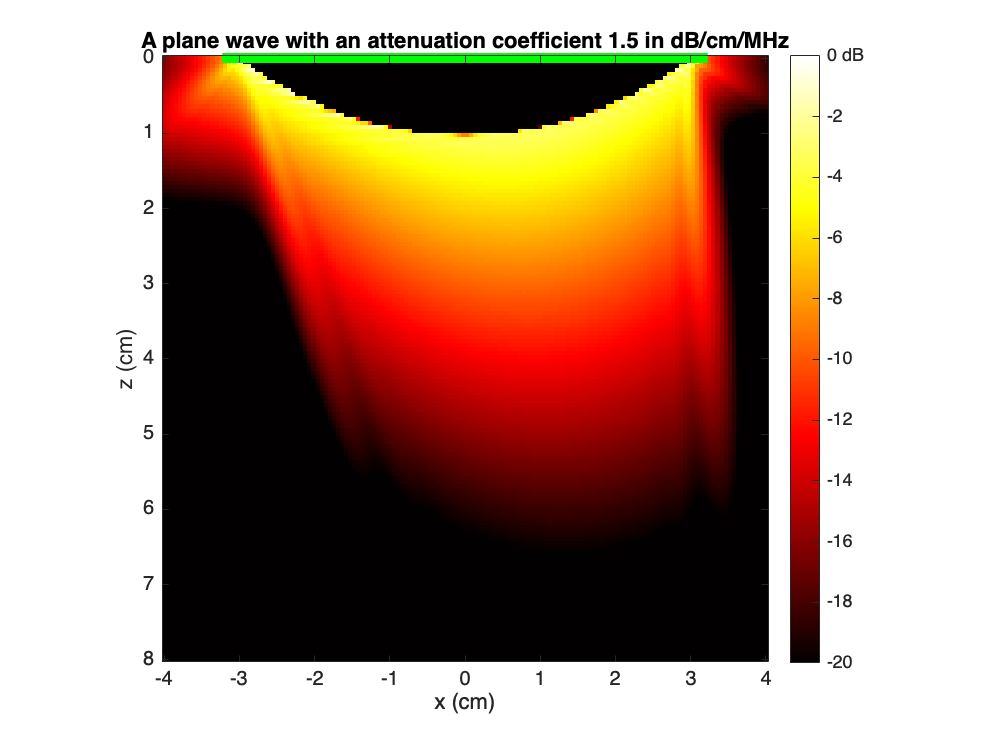

param = struct with fields:
             fc: 3570000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 1.5000


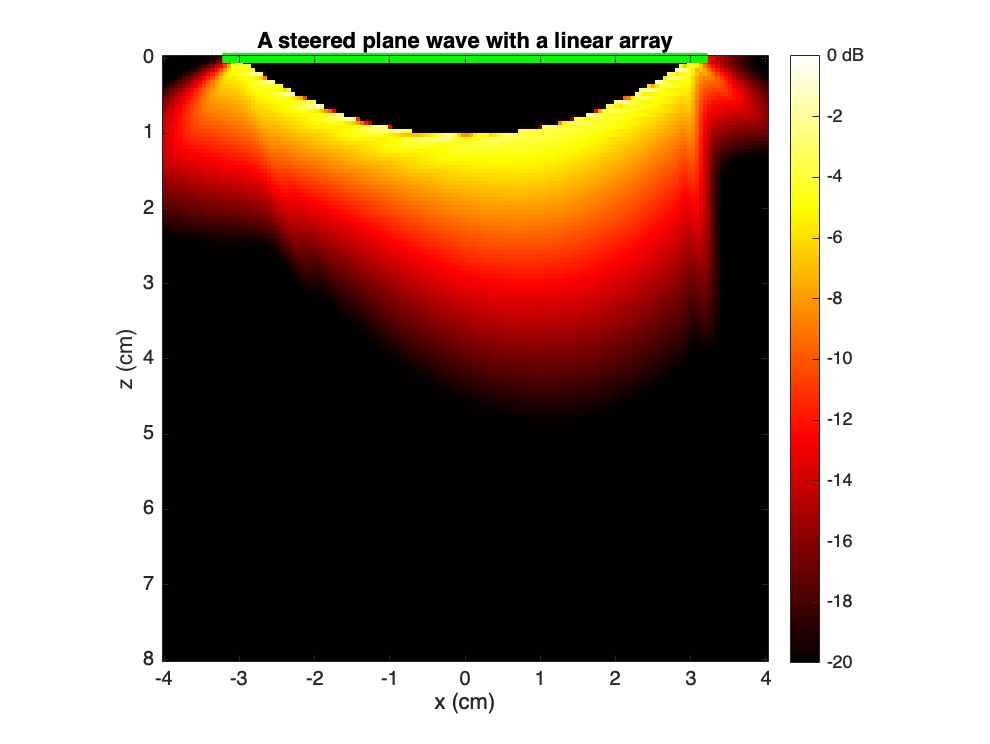

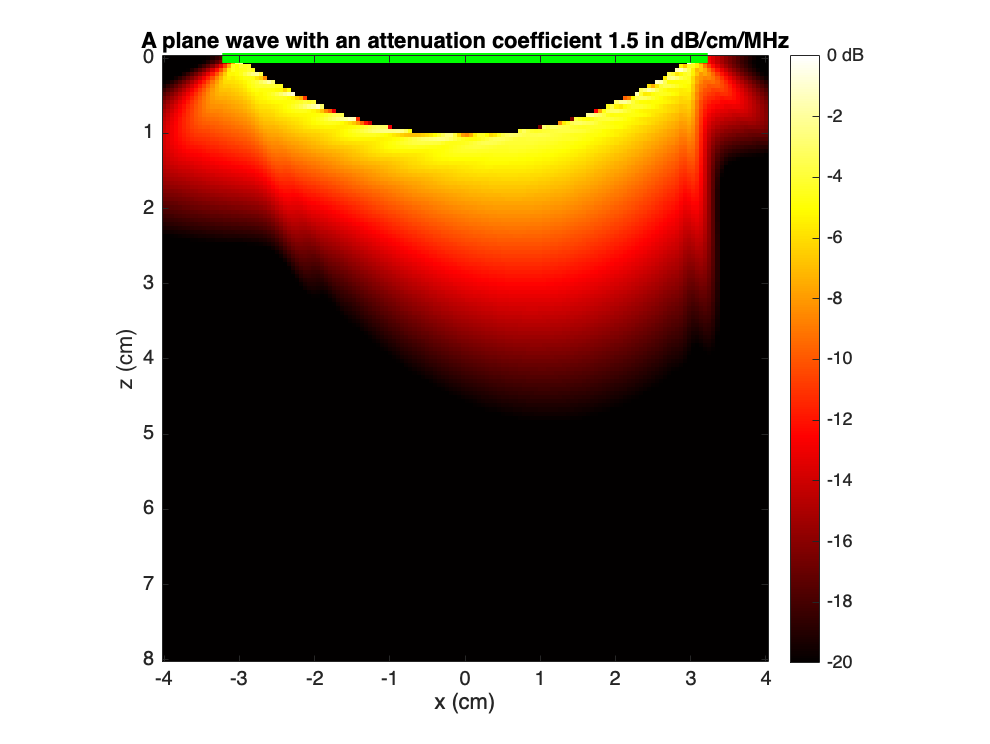

param = struct with fields:
             fc: 7500000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 1.5000


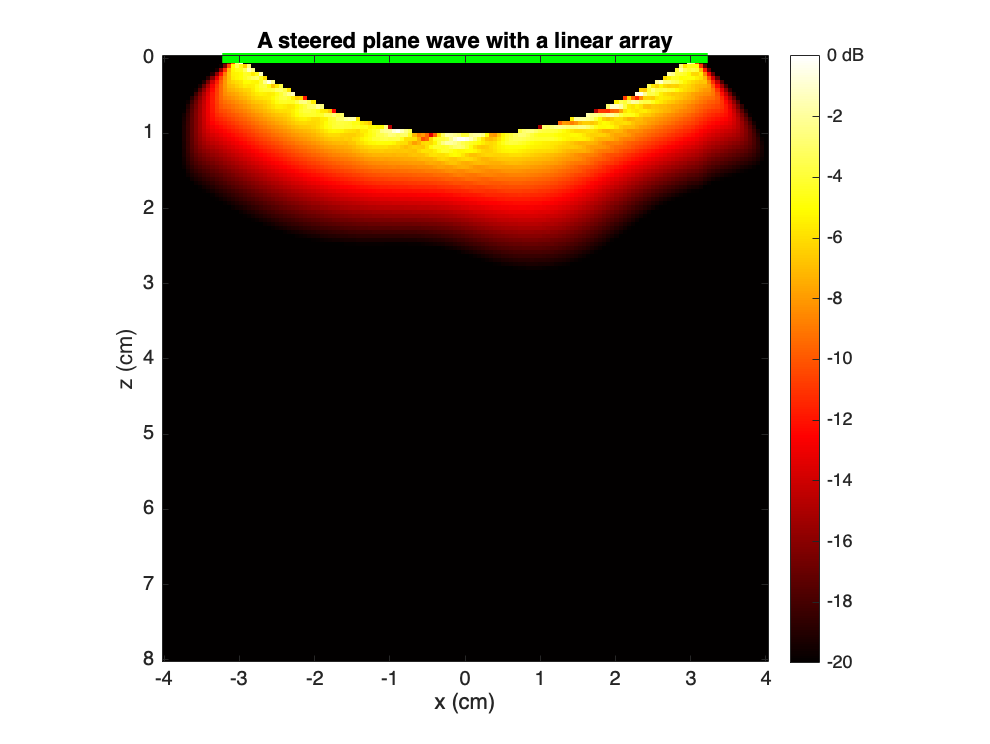

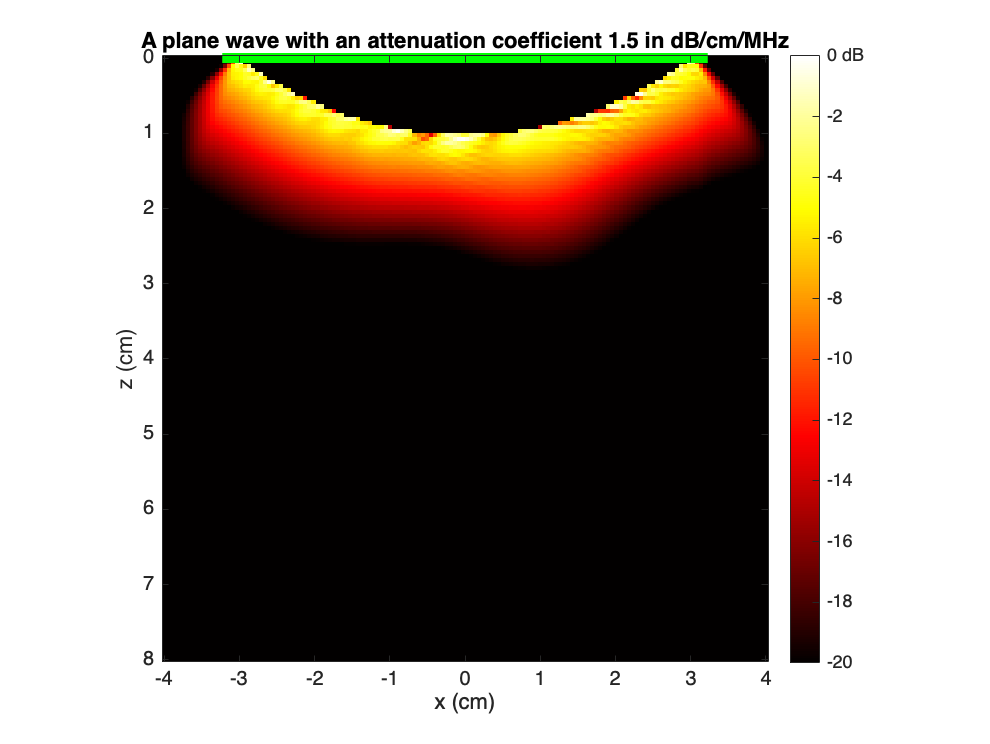

   
param = getparam('C5-2v');

freq_linear = [2.5e6, 3.57e6, 7.5e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 1.5;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 1.5 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end

param = struct with fields:
           fc: 2500000
         kerf: 4.8000e-05
        width: 4.6000e-04
        pitch: 5.0800e-04
    Nelements: 128
    bandwidth: 79
       radius: 0.0496
       height: 0.0135
        focus: 0.0600


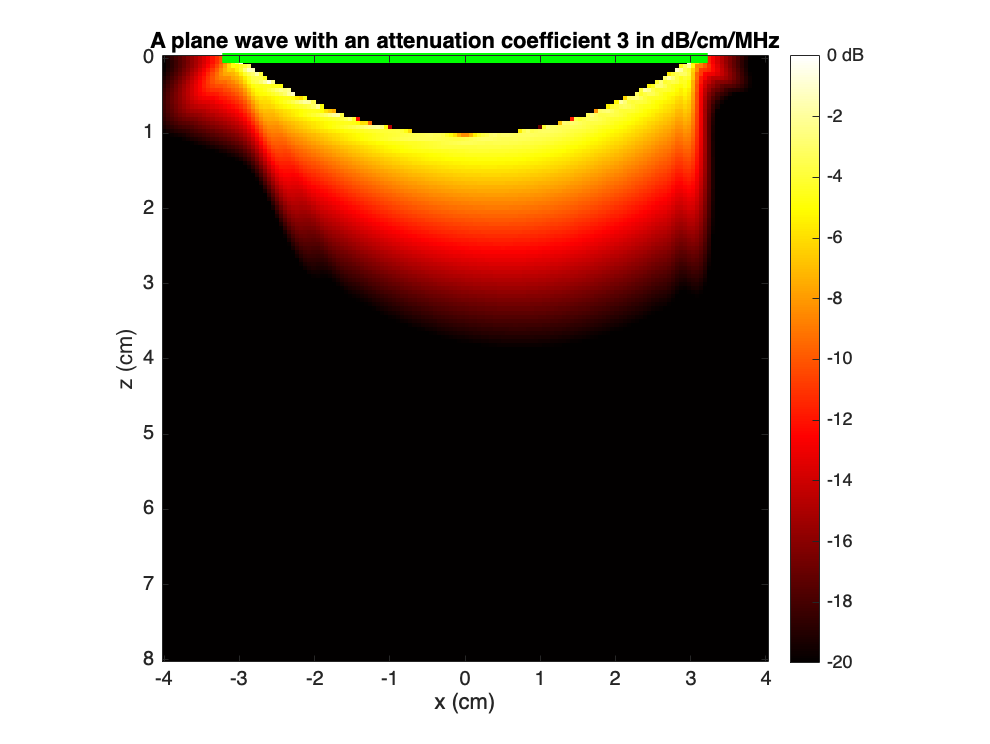

param = struct with fields:
             fc: 3570000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 3


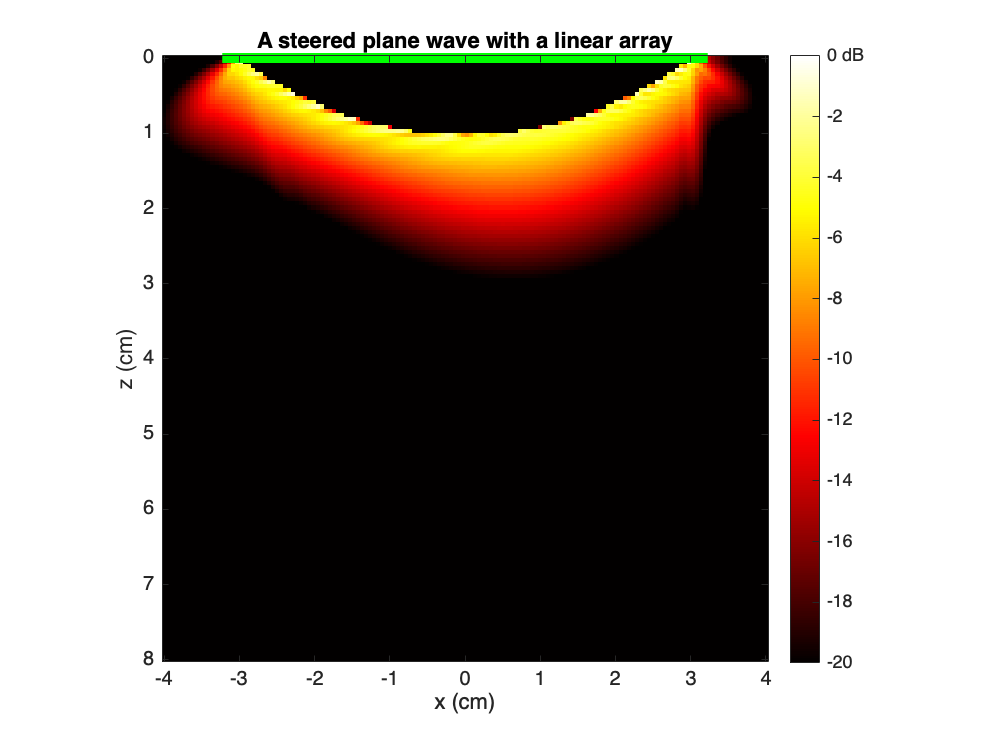

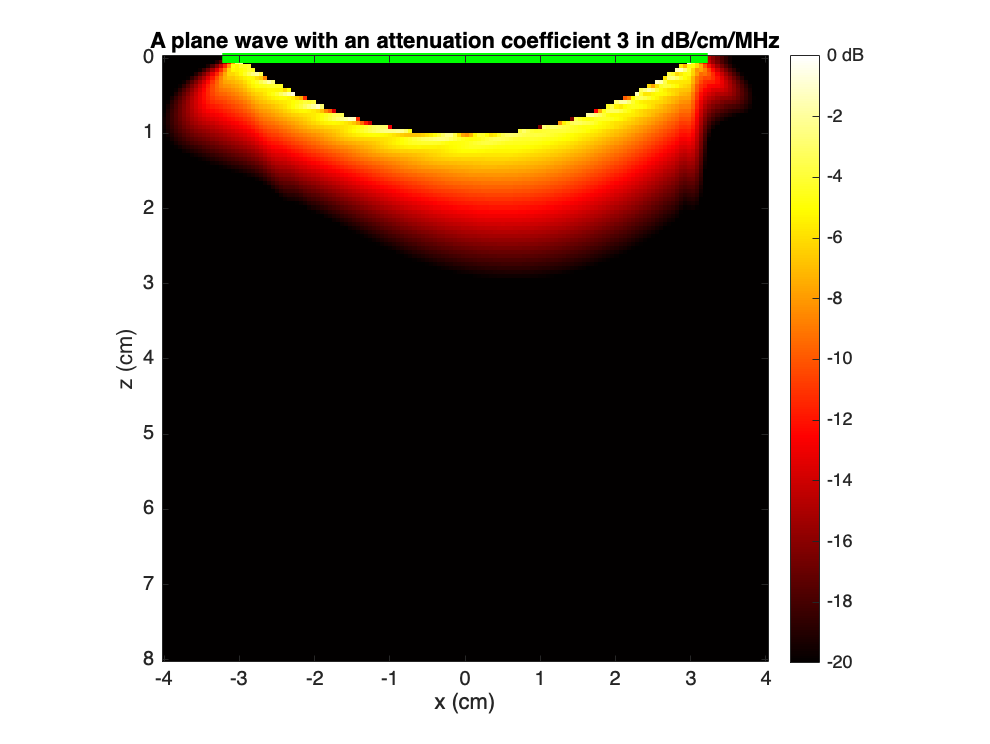

param = struct with fields:
             fc: 7500000
           kerf: 4.8000e-05
          width: 4.6000e-04
          pitch: 5.0800e-04
      Nelements: 128
      bandwidth: 79
         radius: 0.0496
         height: 0.0135
          focus: 0.0600
    attenuation: 3


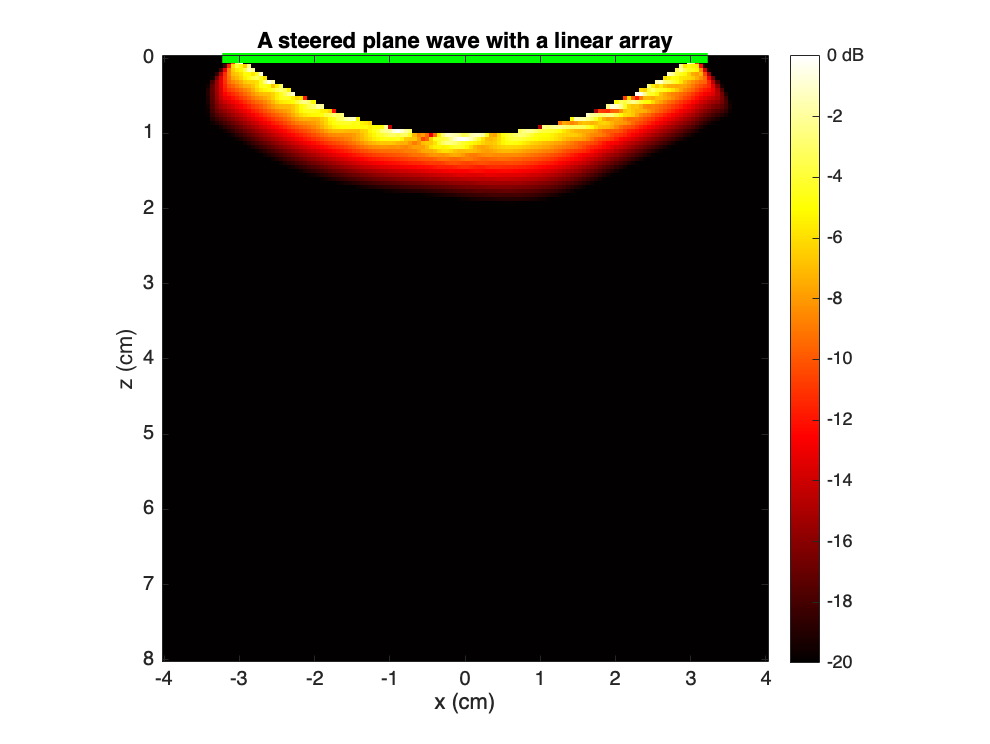

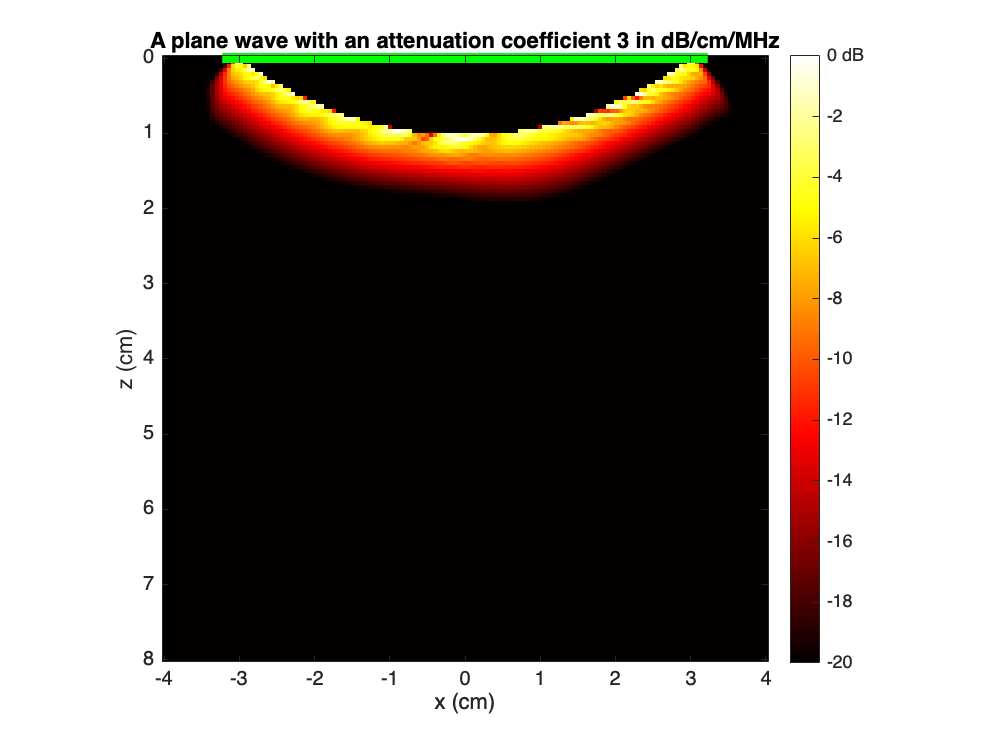

param = getparam('C5-2v');

freq_linear = [2.5e6, 3.57e6, 7.5e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 3;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 3 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end